# EKG Classification using Machine Learning and Feature Extraction with Domain Knowledge

This example shows how to classify human electrocardiogram (ECG) signals using Machine Learning algorithms. We will go through the workflow of feature extraction and training various machine learning models that can recognize the following heart rhythms:

- *Normal Sinus Rhythm*

- * Arrythmia*

The original ECG data comes from the PhysioNet 2017 Challenge, which is available at [https://physionet.org/challenge/2017/.](https://physionet.org/challenge/2017)

clear;

## Prepare Data

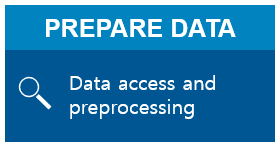

### Load and Preprocess Data

load PhysionetData.mat

This adds two variables to our workspace:

- `Signals` - cell array that holds ECG Signals

- `Labels` - categorical array that holds corresponding ground-truth labels

Signals(1:5)
Labels(1:5)
summary(Labels)

As we can see in the preview, the signal length varies (see `Signals` variable). Let's create a [histogram](https://uk.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html) that shows the length of the signals.

figure
plotSignalLengths(Signals)

Most of the ECG signals are 9000 samples long, but there is some variability.

Visualize a segment of one signal from each class.

Here are two common characteristics of AFib signals:

- Spaced out at irregular intervals.

- Lack a P wave, which pulses before the QRS complex in normal heartbeat.

visualizeECGSignals(Signals)

Since the ECG Signals are different lengths, we need to first pad and truncate them so they are all 9000 samples long. 

The function `segmentSignals` ignores signals with fewer than 9000 samples. If the signal is over 9000 samples, `segmentSignals` breaks it into as many 9000-sample segments as possible and ignores the remaining samples.

For example, a signal with 18500 samples becomes two 9000-sample signals and the remaining 500 samples are ignored.

[Signals,Labels] = segmentSignals(Signals,Labels);

### **Feature extraction**

Machine learning models use features (or predictors) as input (called dependent variables) and return a predicted value as the output (called independent variable). Features can be external measurements or any other values related to the output. The latter one can be seen as internal features which can be generated through transformation of the original data.

Different features can be extracted or generated from the raw data. In this example we are using the following features:

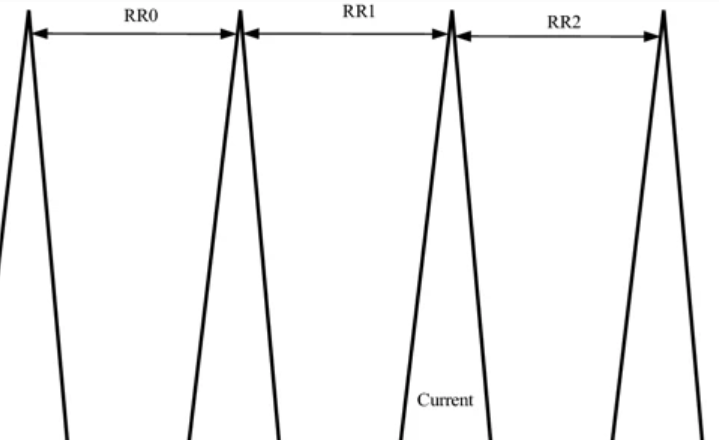        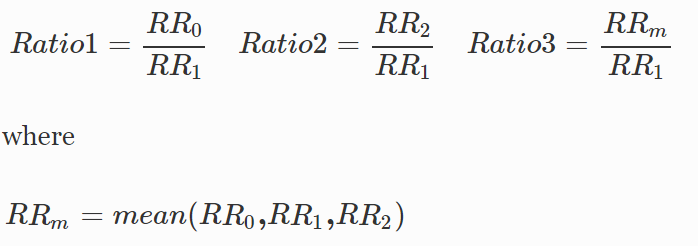

We add 2 further features: the Ampitude of the R Peaks from the two signal channels in the database, bringing us to a total of 8 features.

### **Load Feature Data**

We will load the pre-computed features.

The variable `variableNames` contains all the names of the features. The last column represents the labels (abnorm=0 means that the heartbeat is normal).

load ECG_ML_Features_DK

variableNames = ECGFeatures_DK.Properties.VariableNames;

Note: If you are interested in seeing the code for the feature extraction, please see the separate live script: `ExtractECGFeatures`. 

### Prepare Data for Training

In order to be able to evaluate the performance of the model/s, we split our data set into two subsets: a train set and a test set. The train set will be used to train the model/s while the test set will be used after the training to evaluate the performance on this new (unseen) data.

It is recommended to use between 60 and 90% of the entire data for training and the rest for testing.

In this example, we will use 80% of data for training and remaining for testing.

% partition data into training and testing
percentTrain = 0.8;
[observations, features] = size(ECGFeatures_DK);
idx = randperm(observations);
numTrain = round(percentTrain*observations);

trainData = ECGFeatures_DK(idx(1:numTrain),:);
testData =ECGFeatures_DK(idx(numTrain+1:end),:);

Note: Another way to split the data is to use [cvpartition](https://uk.mathworks.com/help/stats/cvpartition.html).

## Train Model

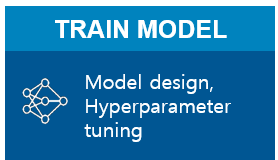

### Option 1: Train using Classification Learner

Use the [Classification Learner App](matlab: web(fullfile(docroot, 'stats/classificationlearner-app.html'))) to interactively train, compare and select classifiers.  One of the biggest challenges in machine learning is that there are many different machine learning algorithms that could be applied to the same problem, and there is no way of knowing ahead of time which will work best. The Classification Learner App gives us an easy way to try out many different modeling techniques very quickly.

Once the best model is trained, you can export it in the MATLAB workspace as `trainedModel` variable, or automatically generate the function to programatically train model/s.  Then you can use the exported model to make predictions on new data (test set).

To open the Classification Learner App, you can either run the command below or go to APPS and click on  .

classificationLearner

- Start a `New Session` and choose` trainData` variable from the workspace as your data (in Data Set Variable). Make sure that `abnormal` is selected as the `Response` and all tickboxes of the `Predictors` are ticked (except for `abnormal`). Keep `Validation` section as it is (`Cross-Validation` with `5 folds`) and click on `Start Session`.

- In `Model Type`, choose `All Quick-To-Train` and start training by clicking on `Run`. The training should take only a couple of seconds.

- In the `History `window, you should see the training progress and when done, the final accuracy of each model. The highest accuracy is highlighted in bold. Your results might look similar to this:

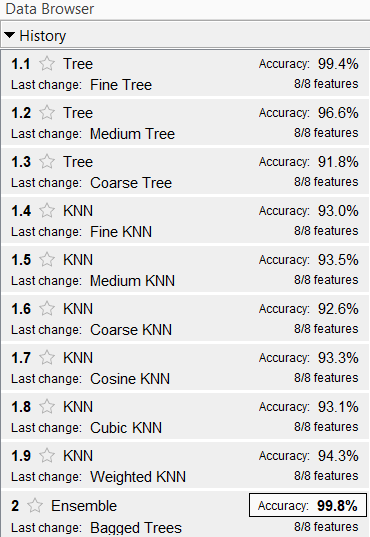

- Explore the confusion matrices of each model by clicking on the individual model and on `Confusion Matrix.`

### Evaluating the trained model 

You can evaluate the performance of the each model on the new (unseen) data set.

- Load the test data set by clicking on the `Test Data` dropdown menu and choosing `From Workspace `(select `testData` as input) and click on `Import`

- Choose a model you want to evaluate the performance of by clicking on the Star Button (Add to favorites) and click on `Test Selected` in the `Test All` dropdown menu (alternatively, do not select any models and click on Test All)

- You can use the confusion matrix to visualise where the model got wrong on the test data

In general, the models perform very well on unseen data.

Note: Alternatively, you can export your trained model or generate a function for further use.

### Option 2: Train programmatically

MATLAB can train models programmatically as well, allowing the user to customize several hyperparameters.

In this exercise, we will use a [medium tree model](https://uk.mathworks.com/help/stats/fitctree.html), a [bagged tree model](https://uk.mathworks.com/help/stats/fitcensemble.html) and a fine Gaussian model (or [SVM](https://uk.mathworks.com/help/stats/fitcsvm.html)).

(Note: The Gaussian model might take a couple of seconds.)


mediumTree = fitctree(trainData,"abnormal", 'MaxNumSplits', 30, 'MinParentSize',15, ...
        "SplitCriterion","gdi");
    
baggedTree = fitcensemble(trainData,"abnormal", 'Method','Bag',...
        'Learners','tree', 'NumLearningCycles',100);
    
fineGaussian = fitcsvm(trainData, "abnormal");


### **Evaluate the new models**

response = testData.abnormal;
% accuracy of decision tree
preds = predict(mediumTree,testData(:,1:end-1));

testAccTree = sum(preds==response)*100/numel(response)
% accuracy of bagged tree
preds = predict(baggedTree,testData(:,1:end-1));
testAccBaggedTree = sum(preds == response)*100/numel(response)
% accuracy of decision tree
preds = predict(fineGaussian,testData(:,1:end-1));
testAccSVM = sum(preds == response)*100/numel(response)

Note: You can also plot confusion matrices for the individual models to see where the model got wrong by using the command [plotconfusion](https://uk.mathworks.com/help/deeplearning/ref/plotconfusion.html) or [confusionchart](https://uk.mathworks.com/help/stats/confusionchart.html).

## Summary

In this example we built machine learning models that identify heart arrhythmia from ECG waveforms. By leveraging knowledge of the medical domain and signal processing, we extracted more powerful features. We interactively trained a few models with Classification Learner, and compared their performance. Overall, the performace of most models was very good (between 90 and 99%).